arms = 1;
voltas = 5;
raio_interno = 0.4;
raio_externo = 0.5;

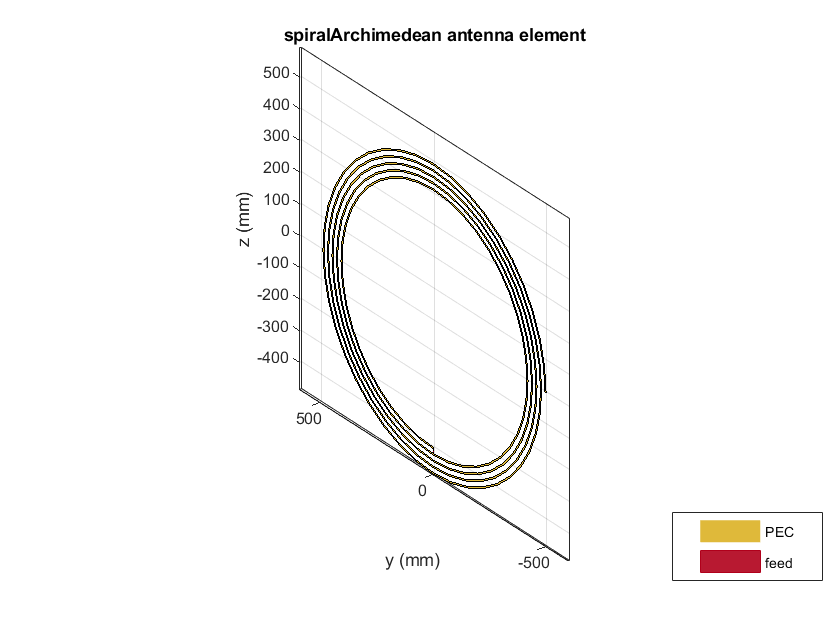

antena = spiralArchimedean('NumArms', arms, 'Turns', voltas, 'InnerRadius', raio_interno, 'OuterRadius', raio_externo, 'Tilt', 90, 'TiltAxis', 'Y');
show(antena)

frequencia = linspace(4000000,10000000,200);
z = impedance(antena,frequencia);
imaginario_z = imag(z)

imaginario_z = 	1.0e+04 *

    0.0094    0.0096    0.0097    0.0098    0.0099    0.0100    0.0102    0.0103    0.0104    0.0105    0.0107    0.0108    0.0110    0.0111    0.0112    0.0114    0.0115    0.0117    0.0118    0.0120    0.0122    0.0123    0.0125    0.0127    0.0129    0.0131    0.0132    0.0134    0.0136    0.0138    0.0141    0.0143    0.0145    0.0147    0.0150    0.0152    0.0155    0.0157    0.0160    0.0163    0.0166    0.0169    0.0172    0.0176    0.0179    0.0183    0.0187    0.0191    0.0195    0.0200


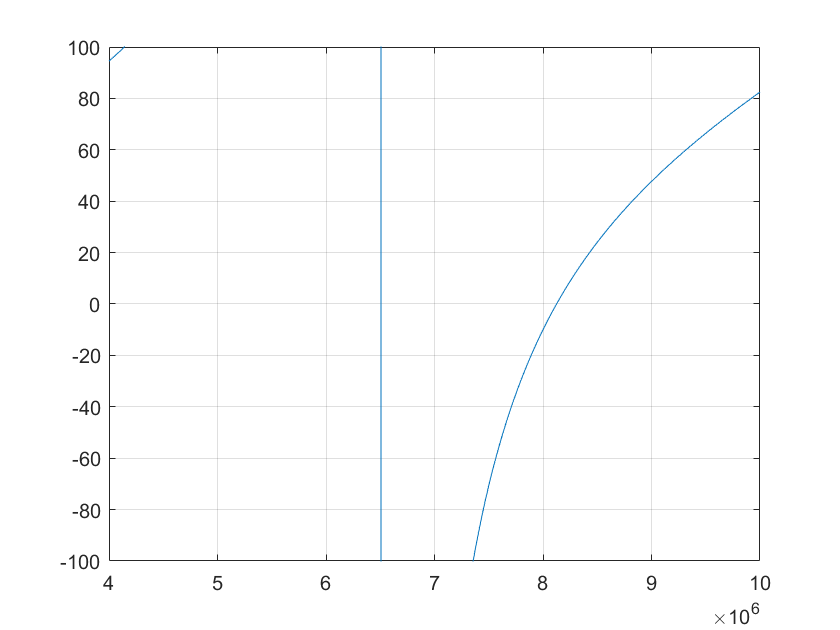

plot(frequencia, imaginario_z)
ylim([-100 100])
grid on

antena_receptora = spiralArchimedean('NumArms', arms, 'Turns', voltas, 'InnerRadius', raio_interno, 'OuterRadius', raio_externo, 'Tilt', 90, 'TiltAxis', 'Y');
show(antena)

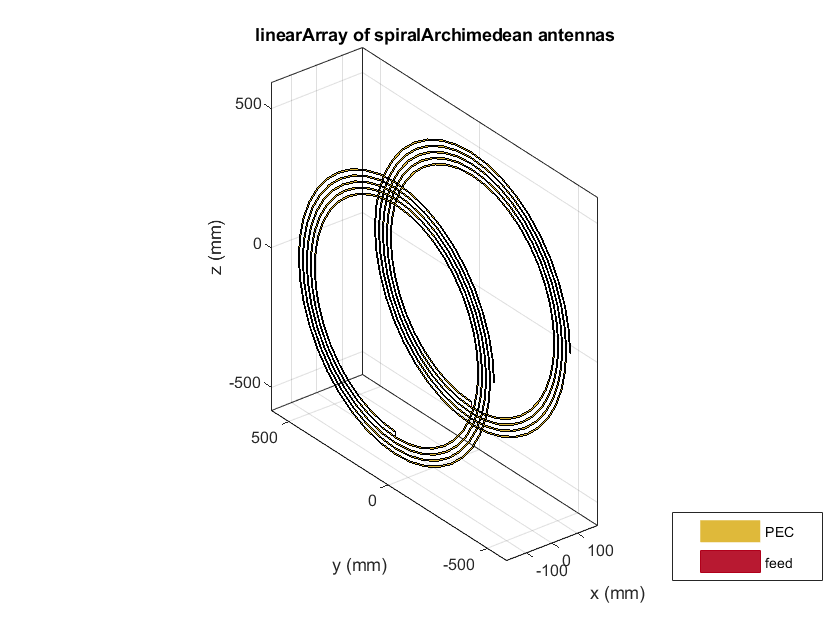

array = linearArray('Element',[antena, antena_receptora]);
array.ElementSpacing = 0.30;
show(array)

ganho = sparameters(array,frequencia)

ganho =   sparameters: S-parameters object

       NumPorts: 2
    Frequencies: [200×1 double]
     Parameters: [2×2×200 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


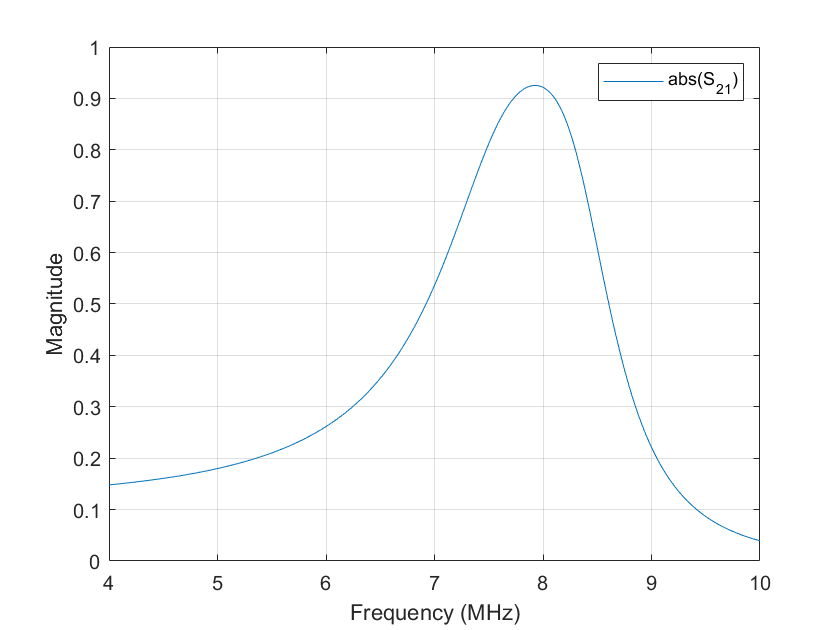

rfplot(ganho,2,1,'abs')

col = 1

col = 1

for d = 0.10:0.08:1;
    array = linearArray('Element',[antena, antena_receptora]);
    array.ElementSpacing = d;
    ganho = sparameters(array,frequencia);
    z(:,col) = rfparam(ganho,2,1) ; 
    col = col + 1;
end

Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 200-by-1.

[X,Y] = meshgrid(frequencia,d);
surface(X,Y,z)